load H1_H3_ag.mat

## Join seasons

H_all_s = zeros(size(H1_H3_ag, 1), size(H1_H3_ag, 2), size(H1_H3_ag, 3));
for s = 1:size(H1_H3_ag,4)
    H_all_s(1+52*(s-1) : 52*s, :, :) = H1_H3_ag(:, :, :, s);
end

## Select season and group


population = [19.9e6; 90.2e6; 173.2e6; 54.1e6];
season = 8;
ag = 4;

[h1, h3, popu] = get_flu_data(H1_H3_ag, season, ag, population);


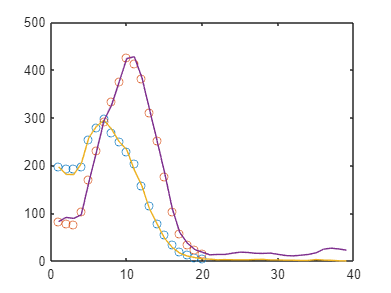


bsteps = exp([-3:0.3:2]);
CP = ones(2, 2);

p13 = 1;
p31 = 1;
b31 = 0.65;
mu = 70;
S0_3 = 0.8;
S0_1 = 0.55;

f = all_f(season, ag); l = all_l(season, ag);

x = squeeze(all_res(season, ag, :)); 
S0_1 = x(1)*popu; S0_3 = x(2)*popu;
b31 = x(3); p31 = x(4); p13 = x(5); mu = x(6);

CP(2, 1) =  p31; CP(1, 2) = p13;
[h1_hat, h3_hat]= ratio_dynamics(h1(f:end), h3(f:end), S0_1*popu, S0_3*popu, b31, CP, mu);

plot([h1(f:l), h3(f:l)], 'o'); hold on;
plot([h1_hat, h3_hat]); hold off;

x0 = [S0_1; S0_3; b31; p31; p13; mu];
ratio_dynamics_obj(x0, h1, h3, popu)



f = 7

l = 10

## Estimate params


lb = [0; 0; 0.1; 0; 0; 1];
ub = [1/30; 1/30; 2; 1; 1; 1];
rr = rand(1); 
x0 = rr*lb+ ub*(1-rr);

[f, l] =  longest_exceeding_index(min(h1, h3), 10);

% [x,~,~,~,~,~,hessian] = fmincon(@(x)(ratio_dynamics_obj(x, h1(f:l), h3(f:l), popu)),x0,[],[],[],[],...
%     lb,ub,@(x)(ratio_dynamics_cons(x, h1(f:l), h3(f:l), popu)));

h = [h1(f:l) h3(f:l)]; H = cumsum(h, 1)./popu;
X = [h, H]; X = X(1:end-1, :);
y = log(h(2:end, 2)) - log(h(2:end, 1));

mdl = fitnlm(X, y, @nlin_func, x0(1:5));
b = mdl.Coefficients.Estimate;
S0_1 = (b(1)).^2; S0_3 = (b(2)).^2;
    b31 = (b(3)).^2; p31 = logsig(b(4)); p13 = logsig(b(5));

## Plot with estimated params

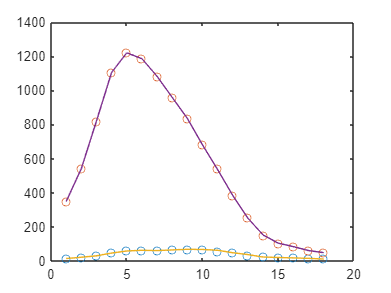

% S0_1 = x(1)*popu; S0_3 = x(2)*popu;
% b31 = x(3); p31 = x(4); p13 = x(5); mu = x(6);


CP = ones(2, 2);
CP(2, 1) =  p31; CP(1, 2) = p13;


[h1_hat, h3_hat]= ratio_dynamics(h1(f:l), h3(f:l), S0_1*popu, S0_3*popu, b31, CP, mu);
plot([h1(f:l), h3(f:l)], 'o'); hold on;
plot([h1_hat, h3_hat]); hold off;

## Parameter estimation over all seasons

options = statset('fitnlm'); options.Display = 'off';

lb = [0.1/30; 0.1/30; 0.5; 0; 0; 1];
ub = [1/30; 1/30; 2; 1; 1; 1];

all_res = nan(10, 4, 6);
all_hes = nan(10, 4, 6);
all_f = nan(10, 4); all_l = nan(10, 4);
all_mdl = cell(10, 4);
for season = 1:10
    for ag = 1:4
        [h1, h3, popu] = get_flu_data(H1_H3_ag, season, ag, population);
        [f, l] =  longest_exceeding_index(min(h1, h3), 5, 14);
        if l-f < 10
            continue;
        end
        rr = rand(1);
        x0 = rr*lb+ ub*(1-rr);
%         [x,~,~,~,~,~,hessian] = fmincon(@(x)(ratio_dynamics_obj(x, h1(f:l), h3(f:l), popu)),x0,[],[],[],[],...
%         lb,ub,@(x)(ratio_dynamics_cons(x, h1(f:l), h3(f:l), popu)));
        h = [h1(f:l) h3(f:l)]; H = cumsum(h, 1)./popu;
        X = [h, H]; X = X(1:end-1, :);
        y = log(h(2:end, 2)) - log(h(2:end, 1));
        
        try 
        mdl = fitnlm(X, y, @nlin_func, x0(1:5), 'Options', options);
        x = mdl.Coefficients.Estimate;
        x(1:3) = x(1:3).^2; x(4:5) = logsig(x(4:5));
        x = [x; 1];
        all_mdl{season, ag} = mdl;
        catch
            continue;
        end
        all_res(season, ag, :) = x;
        all_hes(season, ag, :) = diag(hessian);
        all_f(season, ag) = f;
        all_l(season, ag) = l;
    end
end



function [h1_hat, h3_hat]= ratio_dynamics(h1, h3, S0_1, S0_3, b31, CP, mu)
    
    h = h1 + h3;

%     tidx = find(min(h1, h3)>2);
%     first_t = tidx(1); 
    first_t = 1;
    h1_hat = h1+0.5; h3_hat = h3+0.5;
    H1_hat = sum(h1_hat(1:first_t)); H3_hat = sum(h3_hat(1:first_t));
    for t=(first_t+1):length(h1_hat)
        r_old = (h3_hat(t-1) + 1e-10)/(h1_hat(t-1) + 1e-10);
        r_old = (h3(t-1) + 1e-10)/(h1(t-1) + 1e-10);
        new_imm = mu*CP*[H1_hat; H3_hat];
        r_new = b31*(S0_3 - new_imm(2))*r_old/(S0_1 - new_imm(1));
        
        h3_hat(t) = r_new*h(t)/(1+r_new);
        h1_hat(t) = h(t) - h3_hat(t);
        
        H1_hat = H1_hat+ h1(t); 
        H3_hat = H3_hat+ h3(t); 

        if isnan(r_old)
            raise_error = 1;
        end
    end
end

function L= ratio_dynamics_obj(x, h1, h3, popu)
S0_1 = x(1)*popu; S0_3 = x(2)*popu;
b31 = x(3); p31 = x(4); p13 = x(5); mu = x(6);
CP = ones(2, 2);
CP(2, 1) =  p31; CP(1, 2) = p13;
[h1_hat, h3_hat]= ratio_dynamics(h1, h3, S0_1, S0_3, b31, CP, mu);
p = (h1_hat + 1e-10)./(h3_hat + h1_hat + 2e-10);
L = sum((h1_hat-h1).^2 + (h3_hat-h3).^2);
%L = -sum(h1.*log(p) + h3.*log(1-p));
end

function [c, ceq] = ratio_dynamics_cons(x, h1, h3, popu)
S0_1 = x(1)*popu; S0_3 = x(2)*popu;
b31 = x(3); p31 = x(4); p13 = x(5); mu = x(6);
CP = ones(2, 2);
CP(2, 1) =  p31; CP(1, 2) = p13;
H = sum([h1 h3], 1)';
c = mu*CP*H - [S0_1; S0_3];
ceq = [];
end


function ln_p = ratio_dynamics_t(h_vec, H, p31, p13, S0_1, S0_3, b31)
    % h_vec: 1st element is H1, second is H3
    CP = ones(2, 2);
    CP(2, 1) =  p31; CP(1, 2) = p13;
    imm = CP*H;
    ln_p = log(b31.^2) + 2*log((S0_3 - imm(2))) - 2*log((S0_1 - imm(1))) + log(h_vec(2).^2) - log(h_vec(1).^2);    
    ln_p = ln_p/2;
end

function ln_p = nlin_func(b, X)
    % h_vec: 1st element is H1, second is H3
    S0_1 = (b(1)).^2; S0_3 = (b(2)).^2;
    b31 = (b(3)).^2; p31 = logsig(b(4)); p13 = logsig(b(5));
    ln_p  = zeros(size(X, 1), 1);
    for i = 1:size(X, 1)
        ln_p(i) = ratio_dynamics_t([X(i, 1) X(i, 2)]', [X(i, 3) X(i, 4)]', p31, p13, S0_1, S0_3, b31);
    end
end

function [h1, h3, popu] = get_flu_data(H1_H3_ag, season, ag, population)
    h1 = squeeze(H1_H3_ag(:, 1, ag, season));
    h3 = squeeze(H1_H3_ag(:, 2, ag, season));
    h1 = movmean(h1, 3);
    h3 = movmean(h3, 3);
    popu = population(ag);
end


function [first_t, last_t] = longest_exceeding_index(A, thres, late_start)
if nargin < 3
    late_start = 1;
end
A = A > thres; A(1:late_start-1) = 0;
Ai = find(A==0);
[m, idx] = max(diff(Ai));
first_t = Ai(idx)+1;
last_t = Ai(idx)+m-1;
end